## Fourier Transforms

The Fourier transform is a mathematical formula that transforms a signal sampled in time or space to the same signal sampled in temporal or spatial frequency. In signal processing, the Fourier transform can reveal important characteristics of a signal, namely, its frequency components.

The Fourier transform is defined for a vector *x* with *n* uniformly sampled points by

*y**k*+1=*n*−1∑*j*=0*ω**j**k**x**j*+1.

*ω*=*e*−2*π**i*/*n* is one of the *n* complex roots of unity where *i* is the imaginary unit. For *x* and *y*, the indices *j* and *k* range from 0 to *n*−1.

Consider a sinusoidal signal `x` that is a function of time `t` with frequency components of 15 Hz and 20 Hz. Use a time vector sampled in increments of 1/50 seconds over a period of 10 seconds.

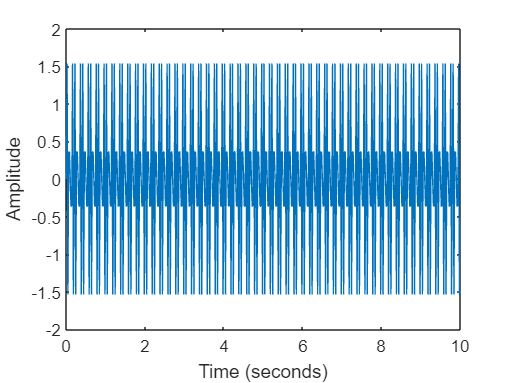

Ts = 1/50;
t = 0:Ts:10-Ts;
x = sin(2*pi*15*t) + sin(2*pi*20*t);
plot(t,x)
xlabel('Time (seconds)')
ylabel('Amplitude')

Computing the Fourier transform of the signal, and create the vector `f` that corresponds to the signal's sampling in frequency space.

y = fft(x);
fs = 1/Ts;
f = (0:length(y)-1)*fs/length(y);

When you plot the magnitude of the signal as a function of frequency, the spikes in magnitude correspond to the signal's frequency components of 15 Hz and 20 Hz.

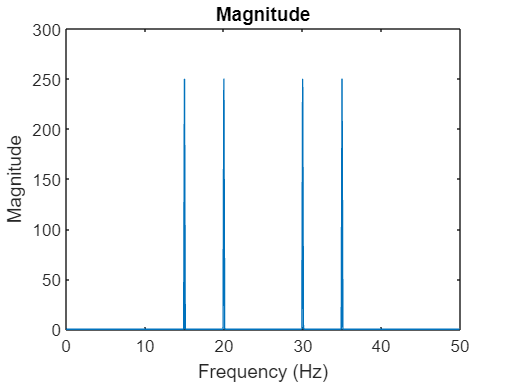

plot(f,abs(y))
xlabel('Frequency (Hz)')
ylabel('Magnitude')
title('Magnitude')

The transform also produces a mirror copy of the spikes, which correspond to the signal's negative frequencies. 

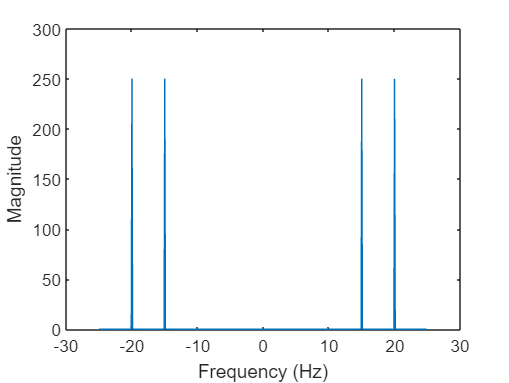

n = length(x);
fshift = (-n/2:n/2-1)*(fs/n);
yshift = fftshift(y);
plot(fshift,abs(yshift))
xlabel('Frequency (Hz)')
ylabel('Magnitude')

**Noisy Signals**

In scientific applications, signals are often corrupted with random noise, disguising their frequency components. The Fourier transform can process out random noise and reveal the frequencies. For example, create a new signal, `xnoise`, by injecting Gaussian noise into the original signal, `x`.

rng('default')
xnoise = x + 2.5*randn(size(t));

Signal power as a function of frequency is a common metric used in signal processing. Power is the squared magnitude of a signal's Fourier transform, normalized by the number of frequency samples. Compute and plot the power spectrum of the noisy signal centered at the zero frequency. Despite noise, you can still make out the signal's frequencies due to the spikes in power.

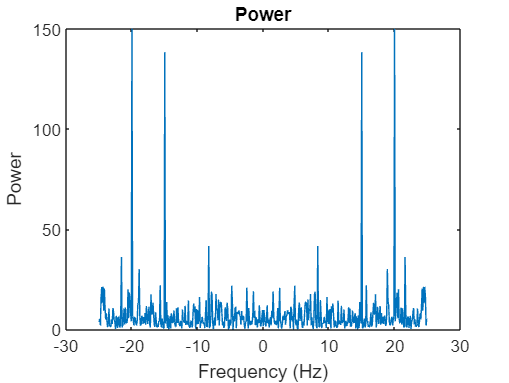

ynoise = fft(xnoise);
ynoiseshift = fftshift(ynoise);
power = abs(ynoiseshift).^2/n; 
plot(fshift,power)
title('Power')
xlabel('Frequency (Hz)')
ylabel('Power')

**Phase of Sinusoids**

Using the Fourier transform, you can also extract the phase spectrum of the original signal. For example, create a signal that consists of two sinusoids of frequencies 15 Hz and 40 Hz. The first sinusoid is a cosine wave with phase −*π*/4, and the second is a cosine wave with phase *π*/2. Sample the signal at 100 Hz for 1 second

fs = 100;
t = 0:1/fs:1-1/fs;
x = cos(2*pi*15*t - pi/4) - sin(2*pi*40*t);

Computing the Fourier transform of the signal. Plot the magnitude of the transform as a function of frequency.

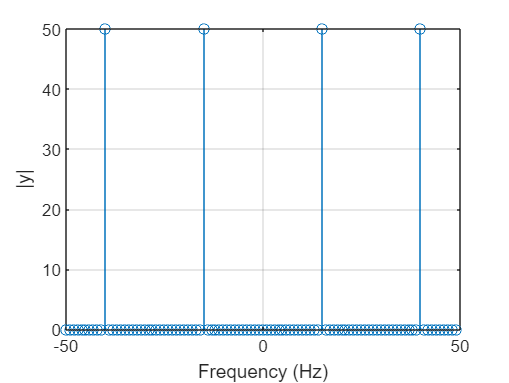

y = fft(x);
z = fftshift(y);

ly = length(y);
f = (-ly/2:ly/2-1)/ly*fs;

stem(f,abs(z))
xlabel("Frequency (Hz)")
ylabel("|y|")
grid

The phase of the transform, removing small-magnitude transform values and plotting the phase as a function of frequency.

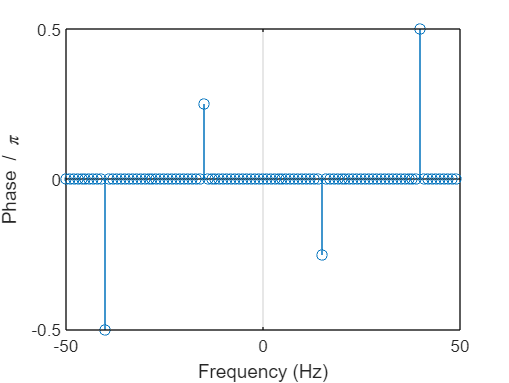

tol = 1e-6;
z(abs(z) < tol) = 0;

theta = angle(z);

stem(f,theta/pi)
xlabel("Frequency (Hz)")
ylabel("Phase / \pi")
grid